# Structural Optimization

## Exercise 3.4

The three-bar truss in Fig. 3.11 is subjected to the force P >0. One wants to maximize the stiffness of the truss by minimizing its compliance Puy ,where uy is the displacement in the y-direction of the node where P is applied. The volume of the truss may not exceed the value V0. The design variables are the cross-sectional areas of the bars: A1, A2, and A3.

a) Formulate the problem as a mathematical programming problem.

b) Solve the optimization problem by using the KKT conditions.

c) Solve the optimization problem by using Lagrangian duality.

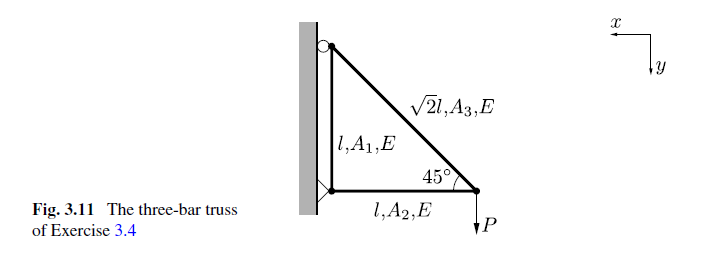

### Answer:

There are three free nodes in the problem. The relationship betwen F and s is evaluated as follow

- $s_1 +s_3 \cdot \sin \theta =0$ (Node 1, y-axis, at the roller)

- $s_2 +s_3 \cdot \cos \theta =0$ (Node 2, x axis, at the load applied)

- ${-s}_3 \cdot \sin \theta +P=0$ (Node 2, y-axis, at the load applied)

Therefore, these equations can be written in a matrix form as follow

$\left[\matrix{0 \cr 0\cr P}\right]=\left[\matrix{1&0&sin\theta  \cr 0&1 & cos\theta\cr 0&0&sin\theta}\right]\left[\matrix{s_1 \cr s_2 \cr s_3}\right]$; $\mathit{\mathbf{F}}={\mathit{\mathbf{B}}}^{\mathit{\mathbf{T}}} \cdot \mathit{\mathbf{s}}$

It is known that ${\sigma \;}_i =\frac{s_i }{A_i }$ and $\varepsilon_{i\;} =\frac{\delta {\;}_i }{L_i }$. Therefore, from Hooke's law, ${\sigma \;}_i =E\cdot \varepsilon {\;}_{i\;}$, then $s{\;}_{i\;} =E\frac{A_{i\;} \cdot \;\delta {\;}_i }{L_i }$. In matrix form, the relationship between $s$ and $\delta \;$can be written as $\left[\matrix{ s_1 \cr s_2 \cr s_3} \right]=E\cdot\left[\matrix{ A_1/L_1&0&0 \cr 0&A_2/L_2 &0 \cr 0&0& A_3/L_3} \right]\left[\matrix{ \delta_1 \cr \delta_2 \cr\delta_3} \right]$; $\mathit{\mathbf{s}}=\mathit{\mathbf{D}}\cdot \delta \;$, while $\delta =\mathit{\mathbf{B}}\cdot \mathit{\mathbf{u}}$.

From this, it can be calculated that $\mathit{\mathbf{u}}$

syms P A1 A2 A3 L E x1 x2 x3 V0 lambda real positive


L1= L;
L2= L;
L3= sqrt(2)*L;

F=[0;0;P];

theta=45*pi()/180

theta = 0.7854


BT=[1 0 sin(theta);0 1 cos(theta);0 0 sin(theta)];

B=transpose(BT);

x_1=x1==P/(E*A1);
x_2=x2==P/(E*A2);
x_3=x3==P/(E*A3);

A1=solve(x_1,A1)

$$A1 = \frac{P}{\text{E}\,x_{1}}$$

A2=solve(x_2,A2)

$$A2 = \frac{P}{\text{E}\,x_{2}}$$

A3=solve(x_3,A3)

$$A3 = \frac{P}{\text{E}\,x_{3}}$$



D=E*[A1/L1 0 0;0 A2/L2 0; 0 0 A3/L3];

K=BT*D*B;

u=simplify(K\F)

$$u = \left(\begin{array}{c} -L\,x_{1}\\ -L\,x_{2}\\ \frac{L\,\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)\,\left(4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2}\right)}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)} \end{array}\right)$$

#### Solution by KKT Condition

The objective function is $f(A_1,A_2,A_3)=P \cdot u_{2y}$ can then be written in $x_{1\;}$and $x_2$ as:

f=simplify(P*u(3))

$$f = \frac{L\,P\,\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)\,\left(4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2}\right)}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}$$

Since $L\;\mathrm{and}\;P$ are constant, then the $g_o$ can be written as

g0=simplify(f/(L*P))

$$g0 = \frac{\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)\,\left(4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2}\right)}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}$$

while the constraint $g_1$can be written as

g1=A1*L1+A2*L2+A3*L3-V0

$$g1 = \frac{L\,P}{\text{E}\,x_{1}}-V_{0}+\frac{L\,P}{\text{E}\,x_{2}}+\frac{\sqrt{2}\,L\,P}{\text{E}\,x_{3}}$$

The Lagrangian function $\mathcal{L}$ as

L=g0+lambda*g1

$$L = \lambda \,\left(\frac{L\,P}{\text{E}\,x_{1}}-V_{0}+\frac{L\,P}{\text{E}\,x_{2}}+\frac{\sqrt{2}\,L\,P}{\text{E}\,x_{3}}\right)+\frac{\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)\,\left(4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2}\right)}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}$$

lambdag1=lambda*g1

$$lambdag1 = \lambda \,\left(\frac{L\,P}{\text{E}\,x_{1}}-V_{0}+\frac{L\,P}{\text{E}\,x_{2}}+\frac{\sqrt{2}\,L\,P}{\text{E}\,x_{3}}\right)$$

dL_dx1=diff(L,x1)

$$dL\_dx1 = \begin{array}{l} \frac{\sqrt{2}\,\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}+\frac{\sqrt{2}\,\sigma_{1}}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}-\frac{\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)\,\sigma_{1}}{2\,{\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}^{2}}-\frac{L\,P\,\lambda }{\text{E}\,{x_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2} \end{array}$$

dL_dx2=diff(L,x2)

$$dL\_dx2 = \frac{\sqrt{2}\,\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)}{2\,\left(x_{1}+2\,\sqrt{2}\,x_{3}\right)}-\frac{L\,P\,\lambda }{\text{E}\,{x_{2}}^{2}}$$

dL_dx3=diff(L,x3)

$$dL\_dx3 = \begin{array}{l} \frac{2\,\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)}{\sigma_{1}}+\frac{2\,\left(4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2}\right)}{\sigma_{1}}-\frac{\sqrt{2}\,\left(4\,x_{3}+\sqrt{2}\,x_{1}\right)\,\left(4\,x_{3}+\sqrt{2}\,x_{1}+\sqrt{2}\,x_{2}\right)}{{\sigma_{1}}^{2}}-\frac{\sqrt{2}\,L\,P\,\lambda }{\text{E}\,{x_{3}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}+2\,\sqrt{2}\,x_{3} \end{array}$$

KKTMat=[lambdag1;dL_dx1;dL_dx2;dL_dx3]==[0;0;0;0];
sol=solve([KKTMat(1),KKTMat(2),KKTMat(3),KKTMat(4)],[x1,x2,x3,lambda])

sol = struct with fields:
        x1: (4*L*P)/(E*V0)
        x2: (4*L*P)/(E*V0)
        x3: (2*2^(1/2)*L*P)/(E*V0)
    lambda: (16*L*P)/(E*V0^2)


syms As1 As2 As3
A_1=(P/(As1*E))==sol.x1;
A_2=(P/(As2*E))==sol.x2;
A_3=(P/(As3*E))==sol.x3;

A_solved1=solve(A_1,As1)

$$A\_solved1 = \frac{V_{0}}{4\,L}$$

A_solved2=solve(A_2,As2)

$$A\_solved2 = \frac{V_{0}}{4\,L}$$

A_solved3=solve(A_3,As3)

$$A\_solved3 = \frac{\sqrt{2}\,V_{0}}{4\,L}$$

#### Solution by Lagrangian Duality

xL_1=dL_dx1==0;
xL_2=dL_dx2==0;
xL_3=dL_dx3==0;

xL1=solve(xL_1,x1)

$$xL1 = \frac{\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }}{\sqrt{\text{E}}}$$

xL2=solve(xL_2,x2)

$$xL2 = \frac{\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }}{\sqrt{\text{E}}}$$

xL3=solve(xL_3,x3)

$$xL3 = \frac{\sqrt{2}\,\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }}{2\,\sqrt{\text{E}}}$$


L_duality=simplify(subs(L,[x1,x2,x3],[xL1,xL2,xL3]))

$$L\_duality = \frac{8\,\sqrt{L}\,\sqrt{P}\,\sqrt{\lambda }-\sqrt{\text{E}}\,V_{0}\,\lambda }{\sqrt{\text{E}}}$$


dL_duality=diff(L_duality,lambda)

$$dL\_duality = -\frac{\sqrt{\text{E}}\,V_{0}-\frac{4\,\sqrt{L}\,\sqrt{P}}{\sqrt{\lambda }}}{\sqrt{\text{E}}}$$


lambda_eqn=dL_duality==0;

lambda_s=solve(lambda_eqn,lambda)

$$lambda\_s = \frac{16\,L\,P}{\text{E}\,{V_{0}}^{2}}$$


x1_duality=simplify(subs(xL1,lambda,lambda_s))

$$x1\_duality = \frac{4\,L\,P}{\text{E}\,V_{0}}$$

x2_duality=simplify(subs(xL2,lambda,lambda_s))

$$x2\_duality = \frac{4\,L\,P}{\text{E}\,V_{0}}$$

x3_duality=simplify(subs(xL3,lambda,lambda_s))

$$x3\_duality = \frac{2\,\sqrt{2}\,L\,P}{\text{E}\,V_{0}}$$


AL_solved1=solve(x1_duality==(P/(As1*E)),As1)

$$AL\_solved1 = \frac{V_{0}}{4\,L}$$

AL_solved2=solve(x2_duality==(P/(As2*E)),As2)

$$AL\_solved2 = \frac{V_{0}}{4\,L}$$

AL_solved3=solve(x3_duality==(P/(As3*E)),As3)

$$AL\_solved3 = \frac{\sqrt{2}\,V_{0}}{4\,L}$$